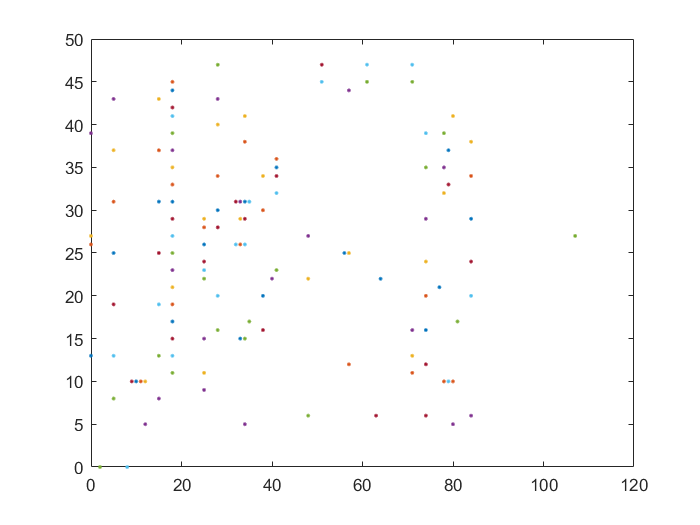

% Since the graph is complete (we can travel from any city to another) in
% this case, I am just storing the position of the cities on the map. The
% weights of the edges between any two cities will be the euclidean
% distance between them.

% Load file to read the graph data
data = fopen("data131.txt", "r");

% Describe the data format of the data file
form = [3 Inf];

% Read the data in a vector. Nth element of the vector are the co-ordinates
% of the nth city.
co_ords = fscanf(data, "%d %d %d", form);
co_ords = permute(co_ords, [2 1]);

co_ords = co_ords(:, 2:3);

% N is the number of cities
N = size(co_ords, 1);

% Plots the map of cities
figure();
for i = 1:N
    plot(co_ords(i, 1), co_ords(i, 2), '.');
    hold on
end
hold off

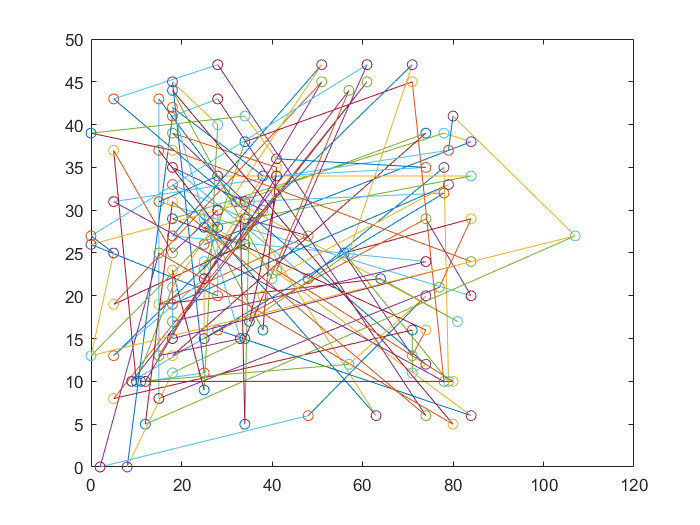


% Since the graph is complete choose any permutation of points to start
% with. I am choosing this permutation randomly.

hamiltonian_cycle = randperm(N);
% hamiltonian_cycle = 1:N;

% Plot the starting hamiltonian cycle
figure()
for i = 1:(N - 1)
    st = hamiltonian_cycle(i);
    fn = hamiltonian_cycle(i + 1);
    plot([co_ords(st, 1), co_ords(fn, 1)], [co_ords(st, 2), co_ords(fn, 2)]);
    hold on
    plot(co_ords(st, 1), co_ords(st, 2), 'O');
    hold on
end
plot(co_ords(hamiltonian_cycle(N), 1), co_ords(hamiltonian_cycle(N), 2), 'O');
plot([co_ords(1, 1) co_ords(N, 1)], [co_ords(1, 2) co_ords(N, 2)]);
hold off

initial_cost = 0;

for i = 1:(N - 1)
    initial_cost = initial_cost + norm(co_ords(hamiltonian_cycle(i), :) - co_ords(hamiltonian_cycle(i + 1), :));
end
initial_cost = initial_cost + norm(co_ords(hamiltonian_cycle(1), :) - co_ords(hamiltonian_cycle(N), :))

initial_cost = 4.4482e+03

% Number of iterations simulated annealing is going to run
total_iter = 100000;

## Simulated Annealing starts here

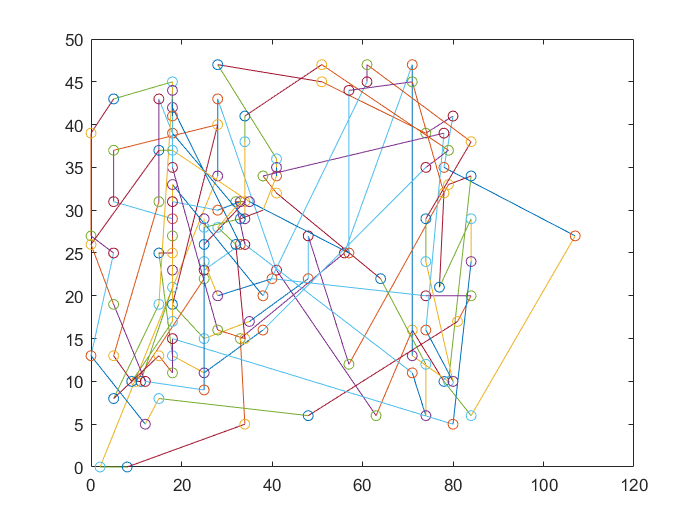

% The control constant
C = 10000;

for iter = 1:total_iter
    % Choose any two positions and then replace with a different path
    % consisting of those vertices. The positions are zero-based.
    
    pos = [randi(N, 1), 1];
    pos(2) = pos(1) + randi(N - 4, 1) + 1;
    
    if (pos(2) > N)
        pos(2) = mod(pos(2), N);
    end
    
    s = pos(1);
    f = pos(2);
    
    initial_cost = 0.0;
    final_cost = 0.0;
    count = 1;
    sub_seg = zeros(1, mod(f - s, N) + 1);
    new_seg = zeros(1, mod(f - s, N) + 1);
    
    while s ~= (mod(f, N) + 1)
        sub_seg(count) = hamiltonian_cycle(s);
        
        % Increment the position
        s = mod(s, N) + 1;
        count = count + 1;
    end
    
    % Randomly permute the positions in the array obtained above and find
    % the final cost
    
    reorder = randperm(mod(pos(2) - pos(1), N) + 1);
    
    % Calculate the cost of the resulting hamiltonian cycle and the initial hamiltonian cycle.
    
    for count = 1:(size(sub_seg, 2) - 1)
        new_seg(count) = sub_seg(reorder(count));
        initial_cost = initial_cost + norm(co_ords(sub_seg(count), :) - co_ords(sub_seg(count + 1), :));
        final_cost = final_cost + norm(co_ords(sub_seg(reorder(count)), :) - co_ords(sub_seg(reorder(count + 1)), :));
    end
    new_seg(size(new_seg, 2)) = sub_seg(reorder(size(new_seg, 2)));
    
    % Find the connecting vertices of the path selected and the overall
    % cycle
    s = pos(1) - 1;
    f = pos(2) + 1;
    
    if (s == 0)
        s = N;
    elseif(f == N + 1)
        f = 1;
    end
    
    % Add the weights of the starting edges and the end edges to both the costs.
    initial_cost = initial_cost + norm(co_ords(hamiltonian_cycle(s), :) - co_ords(sub_seg(1), :)) + norm(co_ords(hamiltonian_cycle(f), :) - co_ords(sub_seg(size(sub_seg, 2)), :));
    final_cost = final_cost + norm(co_ords(hamiltonian_cycle(s), :) - co_ords(new_seg(1), :)) + norm(co_ords(hamiltonian_cycle(f), :) - co_ords(new_seg(size(new_seg, 2)), :));
    
    if ((final_cost < initial_cost) || (rand < exp((initial_cost - final_cost) / C)))
        % change the hamiltonian cycle
        s = pos(1);
        f = pos(2);
        count = 1;
        
        while s ~= (mod(f, N) + 1)
            hamiltonian_cycle(s) = new_seg(count);
            
            s = mod(s, N) + 1;
            count = count + 1;
        end
    end
    
    C = (C + iter) / iter;
end

figure()
for i = 1:(N - 1)
    st = hamiltonian_cycle(i);
    fn = hamiltonian_cycle(i + 1);
    plot([co_ords(st, 1), co_ords(fn, 1)], [co_ords(st, 2), co_ords(fn, 2)]);
    hold on
    plot(co_ords(st, 1), co_ords(st, 2), 'O');
    hold on
end
plot(co_ords(N, 1), co_ords(N, 2), 'O');
plot([co_ords(hamiltonian_cycle(1), 1) co_ords(hamiltonian_cycle(N), 1)], [co_ords(hamiltonian_cycle(1), 2) co_ords(hamiltonian_cycle(N), 2)]);
hold off

optim_cost = 0;

for i = 1:(N - 1)
    optim_cost = optim_cost + norm(co_ords(hamiltonian_cycle(i), :) - co_ords(hamiltonian_cycle(i + 1), :));
end

optim_cost = optim_cost + norm(co_ords(hamiltonian_cycle(1), :) - co_ords(hamiltonian_cycle(N), :))

optim_cost = 1.8324e+03